clear, clc, format short g


## PARTE 1

## 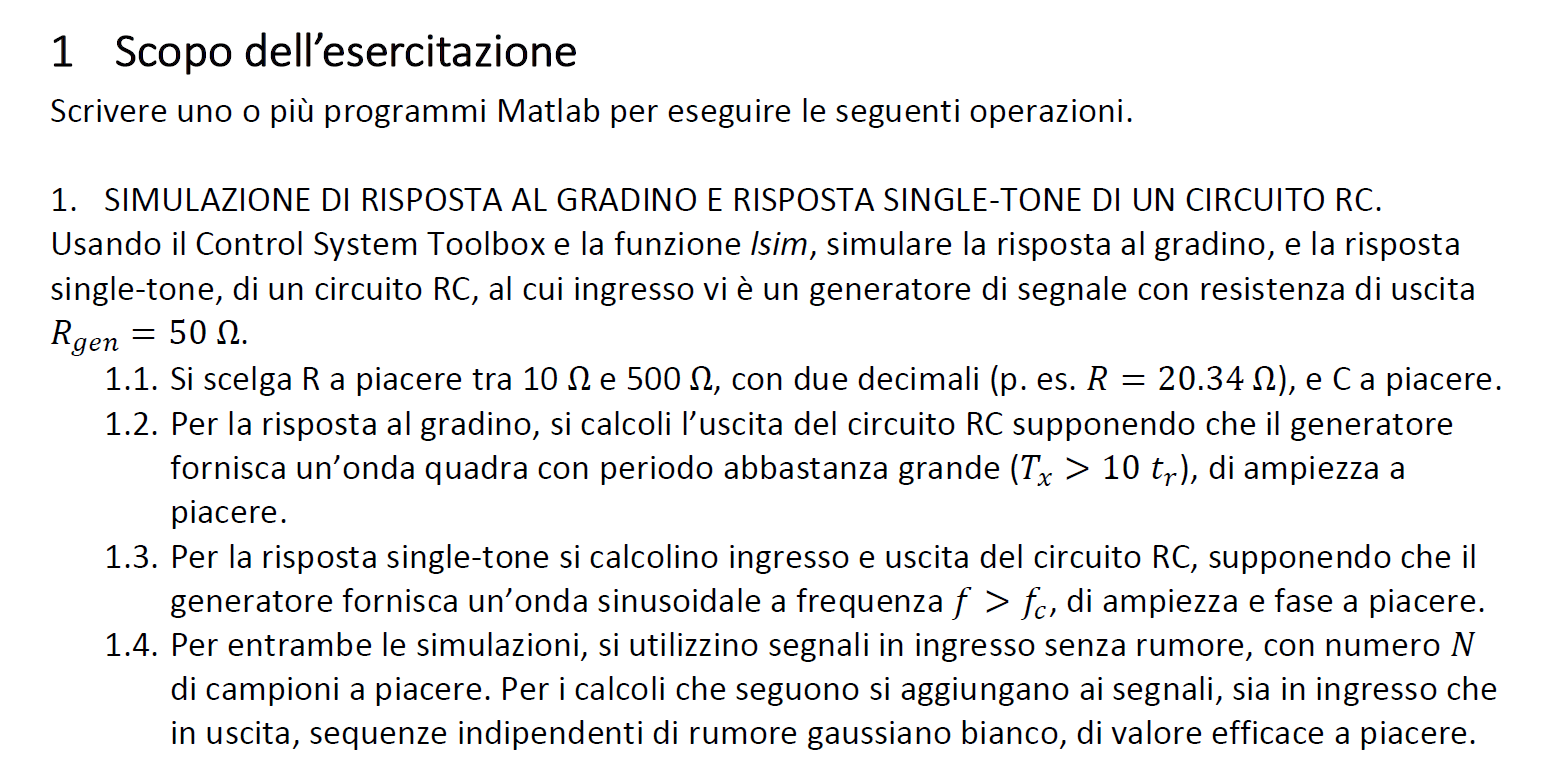


Rgen = 50;
R = 74.38;
C = 15e-9;

tr = C*(R+Rgen)*log(9)

tr =    4.0994e-06



N = 1000;

## definizione tau


tau_step = R*C;
tau_sin = (R+Rgen)*C

tau_sin =    1.8657e-06


## definizione periodi di campionamento

Td = 11*tr % durata simulazione

Td =    4.5093e-05



Ts = Td/N %periodo di campionamento

Ts =    4.5093e-08



n = (0:N-1)' %indici di campionamento

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



t = n*Ts % istanti di campionamento

t =             0
   4.5093e-08
   9.0186e-08
   1.3528e-07
   1.8037e-07
   2.2546e-07
   2.7056e-07
   3.1565e-07
   3.6074e-07
   4.0584e-07


## definizione onda quadra in ingresso

Vpp = 10;

x_step = Vpp*square(2*pi*t/Td)

x_step =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


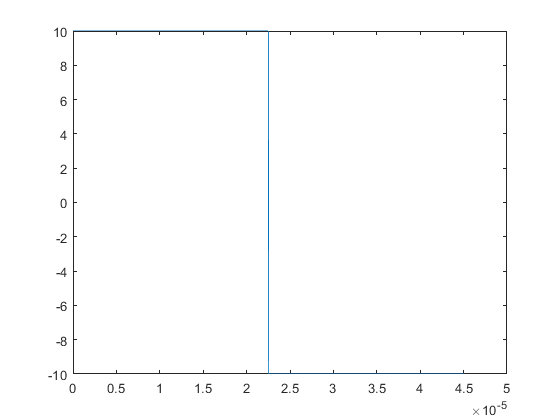


plot(t, x_step)

## definizione fdt

s = tf('s');

H1_dot = 1/(1+tau_step*s)


H1_dot =
 
         1
  ---------------
  1.116e-06 s + 1
 
Continuous-time transfer function.



## definizione risposta gradino

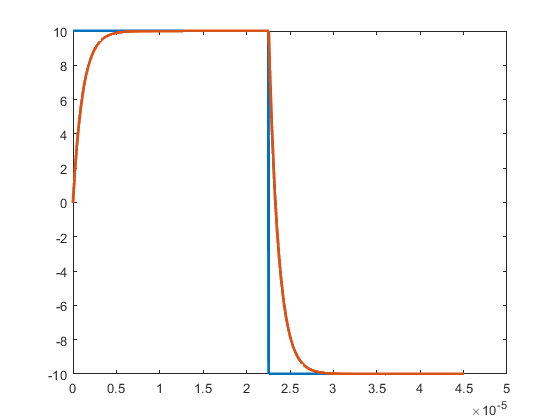

y_step = lsim(H1_dot, x_step, t);

plot(t, x_step, t, y_step, 'linewidth', 2)

## definizione parametri sinusoide

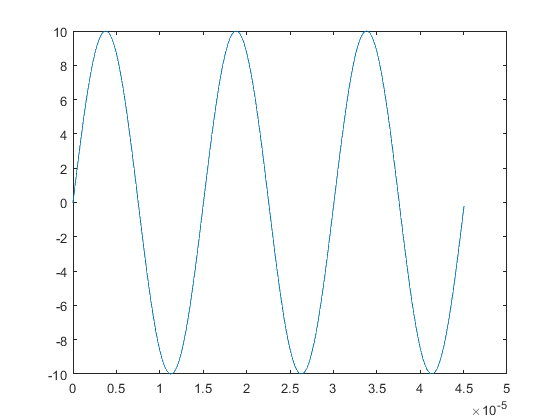

Np = 3;

Tx = Td/Np; 

fx = 1/Tx;

x_sin = Vpp*sin(2*pi*fx*t);

plot(t, x_sin)

## definizione fdt

H_dot = 1/(1+tau_sin*s);


## definizione risposta seno

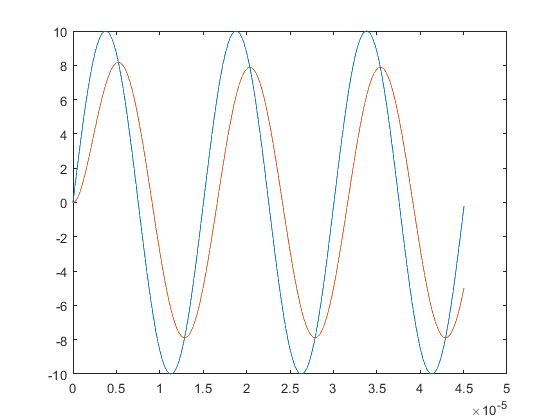

y_sin = lsim(H_dot, x_sin, t);

plot(t, x_sin, t, y_sin)

## 1.4

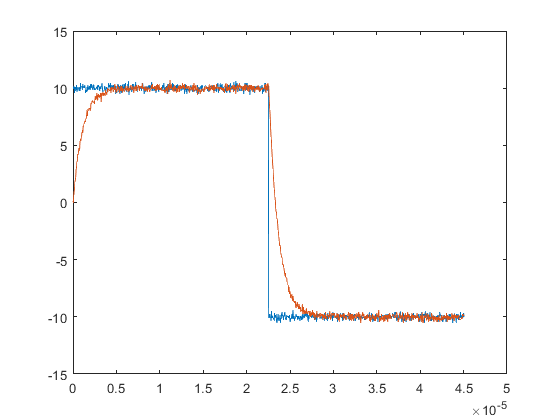

sigma = 0.2;
x_step = Vpp*square(2*pi*t/Td) + randn(N,1)*sigma;

y_step = lsim(H1_dot, x_step, t) + randn(N,1)*sigma;

plot(t,x_step, t, y_step)

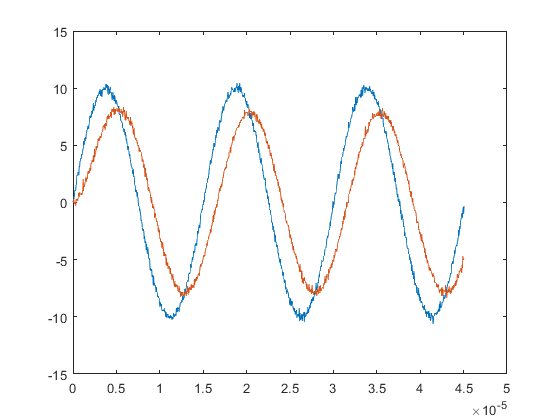


x_sin = Vpp*sin(2*pi*fx*t) + randn(N,1)*sigma;
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;

plot(t,x_sin, t, y_sin)